# ROTEIRO 3

## COMPLEXIDADE N^2

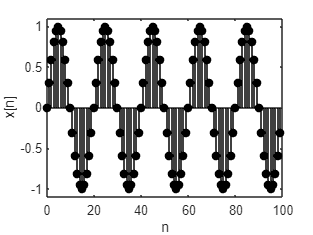


close all 
clc
clear

%%criar sinal ficticio
N=100;
%%freque cia e frequencia de amostragem
%calcular a frequencia que não esta no grid: vazamento espectral
% f=1.1;
f=1;
fs=20;
%%de manos pi a pi
W=2*pi*f/fs;
%%vetor n 
n = 0:N-1;
x = sin(W*n);

%%plotar grafico
figure
stem(n,x,"filled",'k');
ylabel('x[n]');
xlabel('n');
ylim([-1.1,1.1]);

# Fazendo dft

%%achando matriz
%normalizando
DFT = dftmtx(N)*(1/N);
%%achando o espectro
X=DFT*x';

% Omega1=0: 2*pi/N: 2*pi/(N-1)/N;
Omega2 = linspace(0,2*pi*(N-1)/N,N)

Omega2 =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


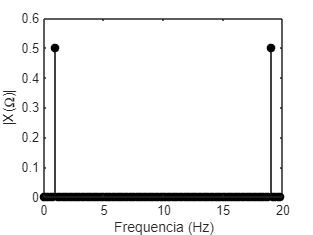

omega = Omega2*fs;

%achando frequencia em hz
f_hz=omega/(2*pi);

%precisa separar em modulo e fase
figure;
stem(f_hz,abs(X),"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')

%plotando de 0 a 2pi precisamos mapear as 100 amostras para espaço de 0 a
%(N-1)*


# MODIFICANDO ASPECTRO


Xabs = abs(X);
Xabs = Xabs(1:N/2+1);
Xabs(2:end) = Xabs(2:end)*2

Xabs =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    1.0000
    0.0000
    0.0000
    0.0000
    0.0000


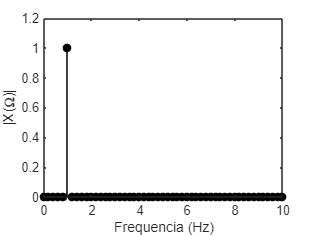


%frequencia modificada
f_hz = f_hz(1:N/2+1);

figure;
stem(f_hz,Xabs,"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')

# ADICIONAR RUIDO

f_ruido = 7.038;
Wruido = 2*pi*f_ruido/fs;
x_ruido = 0.5*sin(Wruido*n)

x_ruido =          0    0.4010   -0.4791    0.1714    0.2742   -0.4991    0.3221    0.1143   -0.4586    0.4337   -0.0595   -0.3625    0.4927   -0.2262   -0.2225    0.4920   -0.3653   -0.0555    0.4316   -0.4602    0.1182    0.3190   -0.4993    0.2777    0.1676   -0.4779    0.4034   -0.0041   -0.3985    0.4802   -0.1753   -0.2708    0.4988   -0.3252   -0.1103    0.4570   -0.4357    0.0636    0.3597   -0.4934    0.2298    0.2188   -0.4913    0.3681    0.0514   -0.4296    0.4618   -0.1222   -0.3158    0.4995


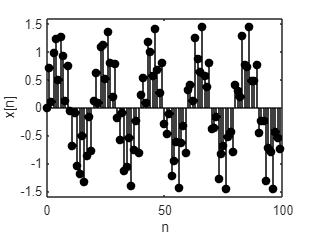

x_modificado = x+x_ruido;

%%plotar grafico do sinal modificado PELO RUIDO
figure
stem(n,x_modificado,"filled",'k');
ylabel('x[n]');
xlabel('n');
ylim([-1.6,1.6]);

## Fazendo DFT

%%achando matriz
%normalizando
DFT_modificado = dftmtx(N)*(1/N);
%%achando o espectro
X_modificado=DFT_modificado*x_modificado';


Omega_modificado = linspace(0,2*pi*(N-1)/N,N)

Omega_modificado =          0    0.0628    0.1257    0.1885    0.2513    0.3142    0.3770    0.4398    0.5027    0.5655    0.6283    0.6912    0.7540    0.8168    0.8796    0.9425    1.0053    1.0681    1.1310    1.1938    1.2566    1.3195    1.3823    1.4451    1.5080    1.5708    1.6336    1.6965    1.7593    1.8221    1.8850    1.9478    2.0106    2.0735    2.1363    2.1991    2.2619    2.3248    2.3876    2.4504    2.5133    2.5761    2.6389    2.7018    2.7646    2.8274    2.8903    2.9531    3.0159    3.0788


omega_modificado = Omega_modificado*fs;


%achando frequencia em hz
f_hz_modificado=omega_modificado/(2*pi);
f_hz_modificado = f_hz_modificado(1:N/2+1);

Xabs_modificado = abs(X_modificado);
Xabs_modificado = Xabs_modificado(1:N/2+1);
Xabs_modificado(2:end) = Xabs_modificado(2:end)*2

Xabs_modificado =     0.0015
    0.0031
    0.0031
    0.0031
    0.0031
    1.0009
    0.0032
    0.0032
    0.0033
    0.0034


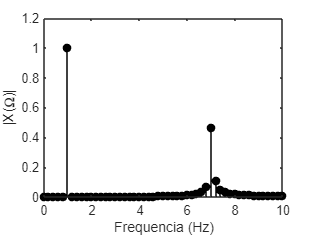


%precisa separar em modulo e fase
figure;
stem(f_hz_modificado,Xabs_modificado,"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')

%plotando de 0 a 2pi precisamos mapear as 100 amostras para espaço de 0 a
%(N-1)*


## densidade espectral de frequencia

figure 
stem(f_hz,Xabs.^2,"filled",'k');
xlabel('Frequencia (Hz)')
ylabel('|X(\Omega)|')

## calculando pela fft

Xfft = fft(x);


